# **YOLOv3-tiny in MATLAB**

#### **Make sure to save your work in your current workspace before running this code!**

% Make sure to save your work on your current workspace before running this code!
clear all, close all, clc;

You only look once (YOLO) is a state-of-the-art, real-time object detection system.

All prior detection systems repurpose classifiers or localizers to perform detection. They apply the model to an image at multiple locations and scales. High scoring regions of the image are considered detections.

YOLO uses a totally different approach by applying a single neural network to the full image. This network divides the image into regions and predicts bounding boxes and probabilities for each region. These bounding boxes are weighted by the predicted probabilities:

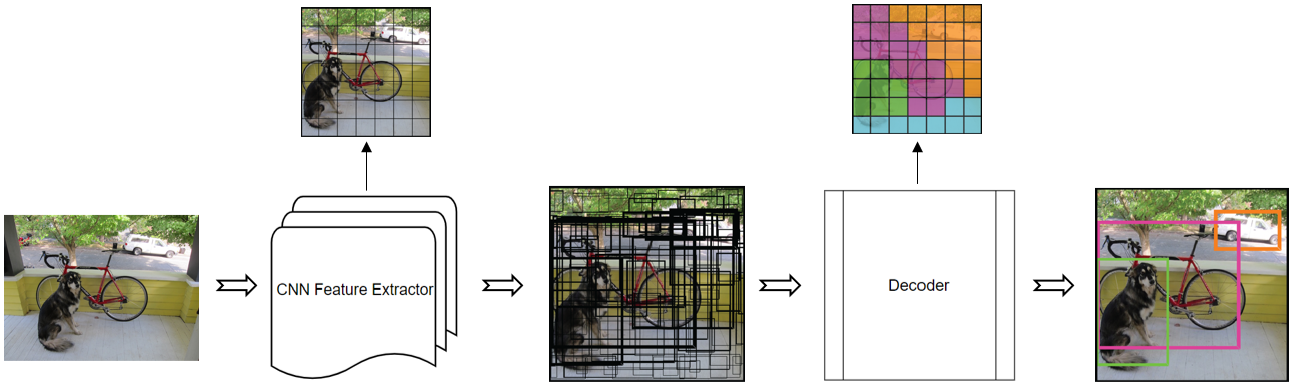

This model has several advantages over classifier-based systems. It looks at the whole image at test time so its predictions are informed by the global context in the image. It also makes predictions with a single network evaluation unlike systems like R-CNN which require thousands for a single image. This makes it extremely fast, more than 1000x faster than R-CNN and 100x faster than Fast R-CNN.

YOLOv3 is the third iteration of the YOLO detection system, It's faster, more accurate, and lightweight. The tiny version of YOLOv3 is an even smaller model designed for constrained environments. With only 33.7MB of weights and 11 convolutional layers, YOLOv3Tiny can achieve an impressive 33.1 mAP score on the COCO dataset.

**Required** **MATLAB** **Add-ons**:

- [Computer Vision Toolbox](https://www.mathworks.com/products/computer-vision.html?s_tid=FX_PR_info)

- [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html?s_tid=FX_PR_info)

- [Image Processing Toolbox](https://www.mathworks.com/products/image.html?s_tid=FX_PR_info)

Written by Yikai Mao with open-source code referenced from:

- [YOLO: Real-Time Object Detection](https://pjreddie.com/darknet/yolo/)

- [Deep Learning : Darknet Importer](https://www.mathworks.com/matlabcentral/fileexchange/71277-deep-learning-darknet-importer)

- [Object Detection Using YOLO v3 Deep Learning](https://www.mathworks.com/help/vision/examples/object-detection-using-yolo-v3-deep-learning.html)

- [yolov3-yolov4-matlab](https://www.mathworks.com/matlabcentral/fileexchange/75305-yolov3-yolov4-matlab)

change log:

- v2: added documentation

- v3: Batch Norm folding

## **Section 1. Load the **`.weights`** file and layer configuration file**

`.cfg` file contains all the layer information of the CNN network. YOLOv3-tiny have 11 convolutional layers with batch normalization enabled to extract features, they use leaky ReLU activation function with $\alpha =0\ldotp 1$. There are also two 1x1 convolutional layers used to construct the final detection at two scopes, they use linear activation function.

`.weights` file is a binary file with all the weights stored in single-precision floating-point format. The file starts with `Major`, `Minor,` and `Revision,` which are version numbers used by the Darknet framework. There is also a `seen` variable and a `transpose` boolean variable but they are not used here. The weights are stored following the order of the layers in the configuration file:

- if (is convolutional layer) in `.cfg` file: `.weights` order = conv_bias --> conv_weights

- if (is convolutional layer && batch norm layer) in `.cfg` file: `.weights` order = bn_offset (still read conv_bias, but used as bn_offset) --> bn_scale --> bn_mean --> bn_var --> conv_weights (no bias for convolutional layer)

`importDarknetNetwork()` will read all the `.cfg` parameters and create the corresponding layers in Matlab Deep Learning format, then load the weights from the `.weights` file.

% downloadable from:
% https://github.com/pjreddie/darknet/blob/master/cfg/yolov3-tiny.cfg
% https://pjreddie.com/media/files/yolov3-tiny.weights
cfgfile = 'yolov3-tiny.cfg';
weightsfile = 'yolov3-tiny.weights';

% yolov3-tiny is trained on the MSFT COCO dataset
namesfile = 'coco.txt';
classNames = categorical(importdata(namesfile));

% importDarknetNetwork() from Darknet Importer
% out = 1 will output weights/bias
% fold = 1 will use folded weights/bias
out = 0;
fold = 1;
% modified by Yikai Mao to fit YOLOv3-tiny
% ↓↓↓ rewrite this part for kilocore ↓↓↓
[lgraph, anchors, numclasses, mask] = importDarknetNetwork(weightsfile, cfgfile, out, fold);

Darknet weights file version info
Major : 0 Minor : 2 Revision : 0
Loading cfg file
Creating graph of network layers for deep learing
--------------------------------------------------------------------
Image input layer : Height - 416 Width - 416 Channel - 3
2D conv layer 1 : Filtersize - 16 : Stride - 1 : Read param# - 432
Skipping batch norm 1
ReLU layer 1 : Scale - 0.1
Max pooling layer 1 : Poolsize - 2 Stride - 2
2D conv layer 2 : Filtersize - 32 : Stride - 1 : Read param# - 4608
Skipping batch norm 2
ReLU layer 2 : Scale - 0.1
Max pooling layer 2 : Poolsize - 2 Stride - 2
2D conv layer 3 : Filtersize - 64 : Stride - 1 : Read param# - 18432
Skipping batch norm 3
ReLU layer 3 : Scale - 0.1
Max pooling layer 3 : Poolsize - 2 Stride - 2
2D conv layer 4 : Filtersize - 128 : Stride - 1 : Read param# - 73728
Skipping batch norm 4
ReLU layer 4 : Scale - 0.1
Max pooling layer 4 : Poolsize - 2 Stride - 2
2D conv layer 5 : Filtersize - 256 : Stride - 1 : Read param# - 294912
Skipping batch 

% ↑↑↑ rewrite this part for kilocore ↑↑↑

## **Section 2. **Visualization of the CNN feature extractor

`analyzeNetwork()` will open a Deep Learning Network Analyzer with an error saying "Unconnected Output" on `conv2d_10` and `conv2d_13.` These two layers are the 1x1 convolutional layers mentioned before, and they themselves are in fact the output of the raw YOLO detection result. A special YOLO detector will be attached to them in later sections and transform the raw output into YOLO format.

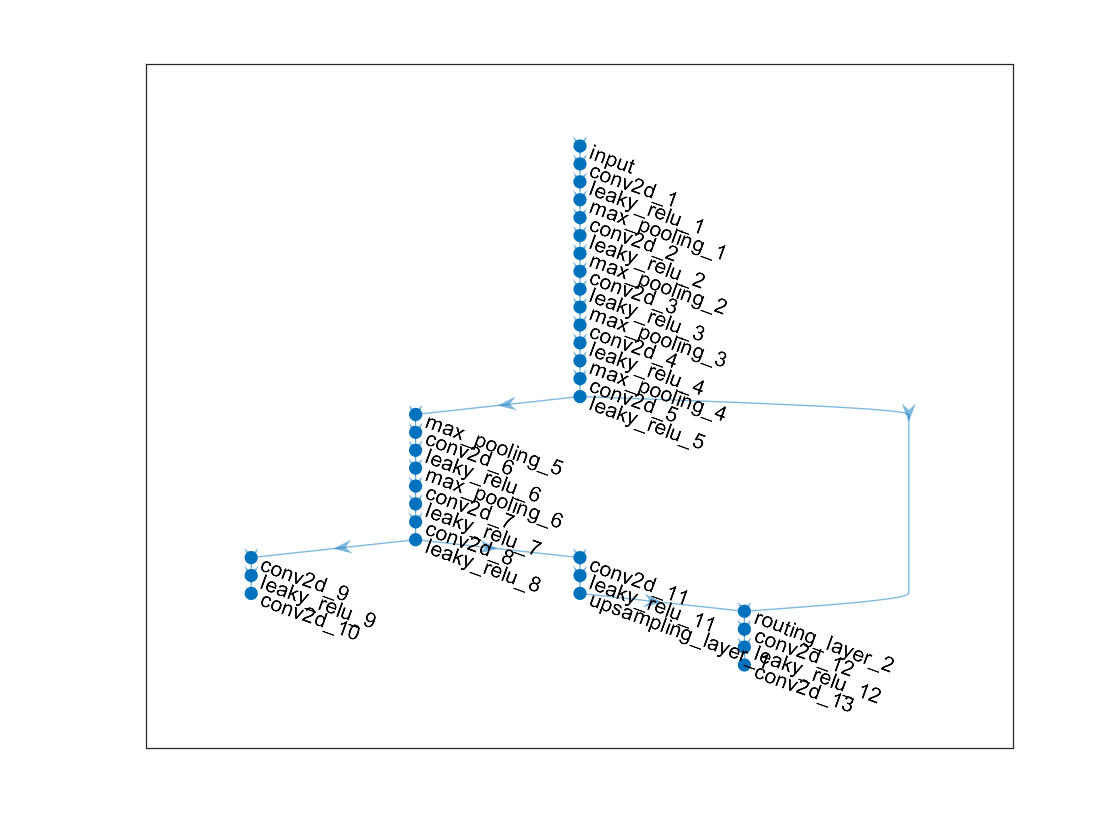

figure,
plot(lgraph);

%analyzeNetwork(lgraph);

% Convert layer graph to dlnetwork
net = dlnetwork(lgraph);

## **Section 3. Inference**

#### **Enter the name of your input image here:**

imgfile = 'images/dog.jpg';
confidenceThreshold = 0.25; % detection threshold, default = 0.25
overlapThreshold = 0.25; % NMS threshold, default = 0.25

Click "Run to End" from Section 3 after changing to a new image to avoid loading the CNN every time.

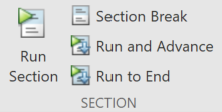

The imported `layerGraph` object was converted into a `dlnetwork` object so Matlab can now pass data through it, the input image is also resized to the input dimension of YOLOv3-tiny (416x416).

% load and resize the input image
% letterbox_image() from Darknet Importer
I = imread(imgfile);
I = im2single(I);
inputSz = net.Layers(1).InputSize(1);
% ↓↓↓ rewrite this part for kilocore ↓↓↓
I = letterbox_image(I, inputSz);
% ↑↑↑ rewrite this part for kilocore ↑↑↑

% Convert to dlarray pbject, input to dlnetwork
XTest = dlarray(I,'SSCB');

% inference
rawOutput = transpose(cell(size(net.OutputNames)));

tStart = tic;

% ↓↓↓ rewrite this part for kilocore ↓↓↓
[rawOutput{:}] = predict(net, XTest, "Outputs", net.OutputNames);
% ↑↑↑ rewrite this part for kilocore ↑↑↑

tEnd = toc(tStart);

## **Section 4. YOLO detector**

Since YOLO is reframing objection detection as a regression problem, the output of the CNN feature extractor is just a convoluted feature map of the original image. The YOLO detector (named `[yolo]` layer in the original `.cfg` file) can be seen as a comprehensive post-processor that: 

- reshapes the raw feature map

- performs regression analysis (apply activation functions)

- calculates the absolute coordinates

- apply Non-Max Suppression

detections = cell(size(rawOutput, 1)); % final result

for i = 1:size(rawOutput, 1)
    % reshape 13x13x255 to 13x13x85x3, rows(y)*columns(x)*predictions*#anchorbox
    % 85 predictions on 3rd dim = 5 bounding box predictions + 80 class predictions
    % 5 bounding box predictions = x, y, width, height, Probability of object
    % 3 anchor boxes on 4th dim
    rawOutput{i} = reshape(rawOutput{i}, size(rawOutput{i}, 1), size(rawOutput{i}, 2), ...
        size(classNames, 1)+5, size(mask{i}, 2));
    predictions = permute(rawOutput{i},[1,2,4,3]);
    
    % apply activations
    % prepare cell position offsets, Cx/Cy in YOLO transform function
    outputSz = size(rawOutput{i},1);
    cellOffset = zeros(outputSz, outputSz, 3, 2);
    for j=1:3 % 3rd dim = 3 detections for each cell
        for k=1:outputSz % 1st dim = rows in Maltab = y direction in YOLO(reversed!)
            % 2nd dim = columns in Matlab = x direction in YOLO(reversed!)
            cellOffset(k,:,j,1) = (0:1:outputSz-1); % Cx in YOLO
            cellOffset(k,:,j,2) = zeros(1,outputSz)+k-1; % Cy in YOLO
        end
    end
    
    % bx = sigmoid(tx) + Cx
    % by = sigmoid(ty) + Cy
    predictions(:,:,:,1:2) = sigmoid(predictions(:,:,:,1:2)) + cellOffset;
    
    % prepare anchor box priors, Pw/Py in YOLO transform function
    % rescale the anchor boxes and match its dimension to the detections
    anchorBox = anchors(mask{i},:)/(inputSz/outputSz); % might not work for other YOLO
    anchorBox = reshape(anchorBox, 1, 1, size(anchorBox,1), size(anchorBox,2));
    
    % bw = Pw * exp(tw), by = Py * exp(ty)
    predictions(:,:,:,3:4) = exp(predictions(:,:,:,3:4)).*anchorBox;
    
    % Pr(object) * IOU(b, object) = sigmoid(to)
    predictions(:,:,:,5:end) = sigmoid(predictions(:,:,:,5:end));
    
    % calculates the absolute coordinates (x, y, w, h)
    predictions(:,:,:,1:4) = predictions(:,:,:,1:4)*(inputSz/outputSz);
    
    % Matlab's NMS function define x and y as the upper-left corner of the box
    % but YOLO define x and y as the center point of the box
    % so extra conversion is needed here
    predictions(:,:,:,1) = predictions(:,:,:,1)-predictions(:,:,:,3)/2; % x
    predictions(:,:,:,2) = predictions(:,:,:,2)-predictions(:,:,:,4)/2; % y
    
    % save the result as #detections*85
    predictions = reshape(predictions, size(mask{i}, 2)*outputSz^2, size(classNames, 1)+5);
    detections{i} = predictions;
end

% concatenate the detections from all YOLO layers
detections = cat(1, detections{:});

% NMS
% extract dlarray to data array
detections = extractdata(detections);

% filter out the low confidence detections
detections = detections(detections(:,5) > confidenceThreshold, :);

% select the best class prediction score
[scores, labels] = max(detections(:, 6:end), [], 2);

% probability of one class = class prediction .* objectness score
scores = scores.*detections(:,5);

% x, y, w, h
bboxes = detections(:,1:4);

% convert to text labels
labels = classNames(labels);

if ~isempty(scores)
    [bboxes,scores,labels] = selectStrongestBboxMulticlass(bboxes, scores, labels,...
        'RatioType','Union','OverlapThreshold', overlapThreshold); % Union/Min
    
    annotations = string(labels) + ": " + string(scores);
    output = insertObjectAnnotation(I, 'rectangle', bboxes, cellstr(annotations));
else
    % nothing detected
    output = I;
end

## **Section 4. Output**

Inference time is approximated (forward propagation only, does not include post-processing time), code is faster if executed outside of this live script.

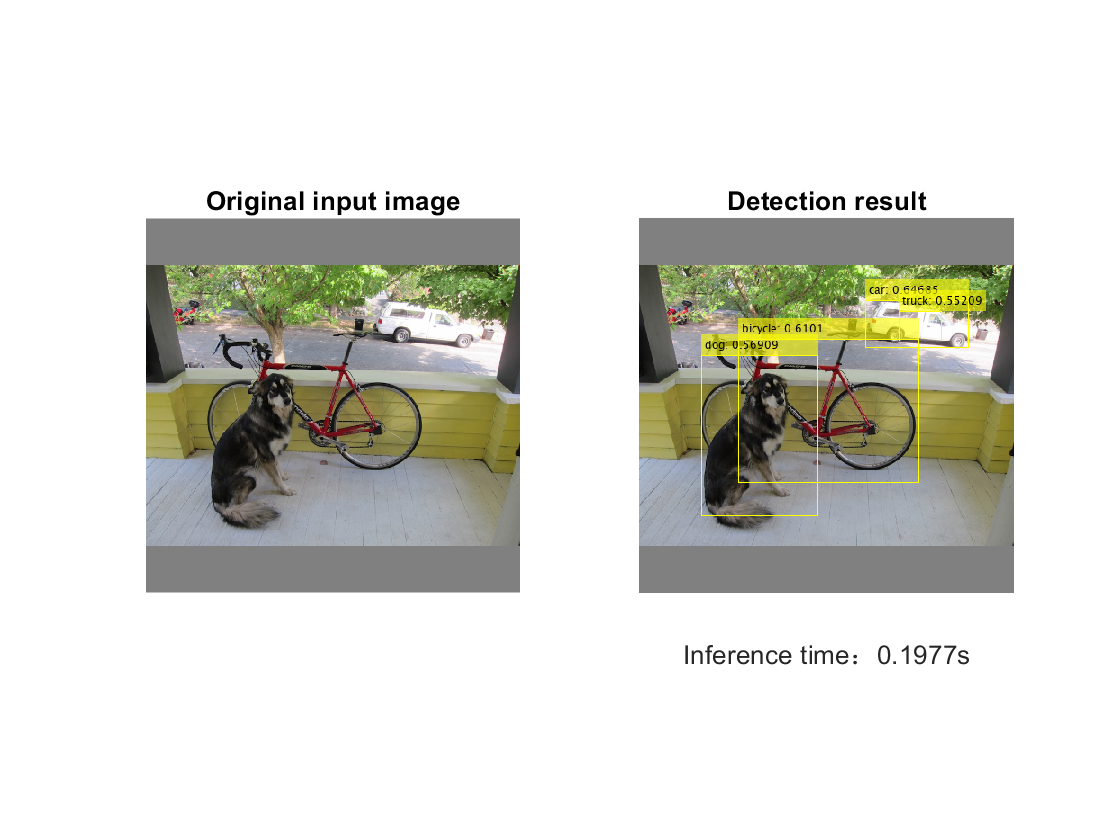

figure

% display original image
subplot(1,2,1);
imshow(I)
title('Original input image')

% display result
subplot(1,2,2);
imshow(output)
title('Detection result')
xlabel(sprintf('Inference time：%.4fs\n', tEnd));